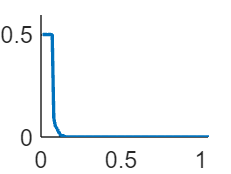

clear all

for l=1:1
    clear biomass1
    clear biomass0
    %filestring=strcat("D1000_biomass_t2500", int2str(l))
    %filestring=strcat(filestring,".m")
    %run(filestring);
    run("D1000_biomass_t19500.m");
        for y=1:400
                heterozygot(y,l)=0.0;
                k=0;
                for x=1:400
                    biomass0(y,x)=biomass_19500_0(y,x);
                    biomass1(y,x)=biomass_19500_1(y,x);
                    if  (biomass0(y,x)+biomass1(y,x))>0.0
                        hetero(y,x)=2*biomass0(y,x)*biomass1(y,x)/((biomass0(y,x)+biomass1(y,x))^2);
                        k=k+1;
                    else
                        hetero(y,x)=0.0;
                    end
                    heterozygot(y,l)=heterozygot(y,l)+hetero(y,x);
                end
                heterozygot(y,l)=heterozygot(y,l)/k;
            end
    
%     plot((1:400)*0.01,heterozygot(1:400))
%     xlabel("Distance from starting edge (cm)")
%     ylabel("Heterozygosity")
%     ylim([0 0.5])
%     xlim([0 2.5])
%     set(gca, 'FontSize', 14)
%     
%     hold on
end

for y=1:400
    avrgHeterozygot(y)=mean(heterozygot(y,:));
    stdHeterozygot(y)=std(heterozygot(y,:));
    sterrHeterozygot(y)=stdHeterozygot(y)/sqrt(5);
end
hold on
plot((1:400)*0.01,avrgHeterozygot(1:400),'LineWidth',2)
%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))
%xlabel("Distance from starting edge (cm)")
%ylabel("Heterozygosity")
%ylim([0 0.5])
%xlim([0 2.5])
set(gca, 'FontSize', 14)

hold on

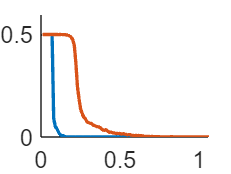




for l=1:1
    clear biomass1
    clear biomass0
    %filestring=strcat("biomass_D10000_t200h_", int2str(l))
    %filestring=strcat(filestring,".m")
    %run(filestring);
    run("D10000_biomass_t5000.m")
        for y=1:400
                heterozygot(y,l)=0.0;
                k=0;
                for x=1:400
                    biomass0(y,x)=biomass_5000_0(y,x);
                    biomass1(y,x)=biomass_5000_1(y,x);
                    if  (biomass0(y,x)+biomass1(y,x))>0.0
                        hetero(y,x)=2*biomass0(y,x)*biomass1(y,x)/((biomass0(y,x)+biomass1(y,x))^2);
                        k=k+1;
                    else
                        hetero(y,x)=0.0;
                    end
                    heterozygot(y,l)=heterozygot(y,l)+hetero(y,x);
                end
                heterozygot(y,l)=heterozygot(y,l)/k;
            end
    
%     plot((1:400)*0.01,heterozygot(1:400))
%     xlabel("Distance from starting edge (cm)")
%     ylabel("Heterozygosity")
%     ylim([0 0.5])
%     xlim([0 2.5])
%     set(gca, 'FontSize', 14)
%     
%     hold on
end

for y=1:400
    avrgHeterozygot(y)=mean(heterozygot(y,:));
    stdHeterozygot(y)=std(heterozygot(y,:));
    sterrHeterozygot(y)=stdHeterozygot(y)/sqrt(5);
end

hold on
plot((1:400)*0.01,avrgHeterozygot(1:400),'LineWidth',2)

%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))


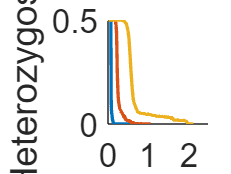


clear heterozygot
for l=1:1
    clear biomass1
    clear biomass0
    %filestring=strcat("biomass_D1000_t475h_", int2str(l+1))
    %filestring=strcat(filestring,".m")
    %run(filestring);
    run("D100000_biomass_t3000.m");
            for y=1:400
                heterozygot(y,l)=0.0;
                k=0;
                for x=1:400
                    biomass0(y,x)=biomass_3000_0(y,x);
                    biomass1(y,x)=biomass_3000_1(y,x);
                    if  (biomass0(y,x)+biomass1(y,x))>0.0
                        hetero(y,x)=2*biomass0(y,x)*biomass1(y,x)/((biomass0(y,x)+biomass1(y,x))^2);
                        k=k+1;
                    else
                        hetero(y,x)=0.0;
                    end
                    heterozygot(y,l)=heterozygot(y,l)+hetero(y,x);
                end
                heterozygot(y,l)=heterozygot(y,l)/k;
            end
    
%     plot((1:400)*0.01,heterozygot(1:400))
%     xlabel("Distance from starting edge (cm)")
%     ylabel("Heterozygosity")
%     ylim([0 0.5])
%     xlim([0 2.5])
%     set(gca, 'FontSize', 14)
%     
%     hold on
end

for y=1:400
    avrgHeterozygot(y)=mean(heterozygot(y,:));
    stdHeterozygot(y)=std(heterozygot(y,:));
    sterrHeterozygot(y)=stdHeterozygot(y)/sqrt(1);
end
hold on
plot((1:400)*0.01,avrgHeterozygot(1:400),'LineWidth',2)
%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))

%errorbar((1:400)*0.01,avrgHeterozygot(1:400), sterrHeterozygot(1:400))
%xlabel("Distance from starting edge (cm)")
ylabel("Heterozygosity",'FontSize',30)
ylim([0 0.5])
xlim([0 2.5])
set(gca, 'FontSize', 20)

hold on

ylim([0 0.5])
xlim([0 1.0])
h=legend('D_b=600','D_b=60','D_b=6 x10^{-3}','Location','east')

h =   Legend (D_b=600, D_b=60, D_b=6 x10^{-3}) with properties:

         String: {'D_b=600'  'D_b=60'  'D_b=6 x10^{-3}'}
       Location: 'east'
    Orientation: 'vertical'
       FontSize: 18
       Position: [0.5842 0.3712 0.3025 0.2938]
          Units: 'normalized'

  Show all properties


rect = [0.68, 0.60, .25, .25];
set(h, 'Position', rect)
tex = text(0.68,0.23,'[cm^2/sec·g]','FontSize',23)

tex =   Text ([cm^2/sec·g]) with properties:

                 String: '[cm^2/sec·g]'
               FontSize: 23
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [0.6800 0.2300 0]
                  Units: 'data'

  Show all properties


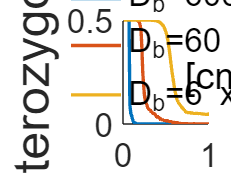

%legend('boxoff')
set(gca, 'FontSize', 20)
%legend('FontSize', 18)
ylabel("Heterozygosity",'FontSize',30)
% rect = [0.60, 0.55, .25, .25];
% set(h, 'Position', rect)
 legend('boxoff')
% set(gca, 'FontSize', 20)
 legend('FontSize', 20)
%set(gca,'xtick',[])
hold off

clear all


%semilogy((1:400)*0.01,avrgHeterozygot(1:400))